Consider the following system with 2 dofs [1,2]


$$\ddot{q}_1+2D_1\omega_1\dot{q}_1+\omega_1^2q_1+\frac{\omega_1^2}{2}(3q_1^2+q_2^2)+\omega_2^2q_1q_2+\frac{\omega_1^2+\omega_2^2}{2}q_1(q_1^2+q_2^2)=\epsilon f_1\cos\Omega t,\\

\ddot{q}_2+2D_2\omega_2\dot{q}_2+\omega_2^2q_2+\frac{\omega_2^2}{2}(3q_2^2+q_1^2)+\omega_1^2q_1q_2+\frac{\omega_1^2+\omega_2^2}{2}q_2(q_1^2+q_2^2)=0.$$


We select the parameters $\omega_1=2$, $\omega_2=4.5$, $D_1=0.01$ and $D_2=0.2$ and $f_1$ is set to 0.02.

The damped backbone curve is defined as


$$\mathcal{B}(\epsilon,\Omega)=\mathrm{argstat}_{\Omega} \mathcal{L}(x)$$


where $\mathcal{L}$ is an objective functional to be optimized. For example, we may use the amplitude of the first oscillator, i.e., 


$$\mathcal{L}(x)=\sqrt{\frac{1}{T}\int_0^T x_1^2(t)\mathrm{d}t}$$


or 


$$\mathcal{L}(x)=\max_{0\leq t\leq2\pi/\Omega} |x_1(t)|$$


as the objective functiona. The stationary solution of $\mathcal{L}$ gives a point on the backbone curve.

clear all

#### Setup model

[mass,damp,stiff,fnl,fnl_dx,fext] = build_model_func();
DS = DynamicalSystem();
set(DS.Options,'notation','fun_handle')
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl,'dfnldx',fnl_dx);
% Forcing
epsilon = 1;
kappas = [-1; 1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

### Forced response curve

om = eig(stiff,mass);
om = sqrt(om);
freqRange = [0.8 1.2]*om(1);
nCycles = 10;
outdof = 1;
coco = cocoWrapper(DS, nCycles, outdof);
% shooting method
set(coco.Options, 'PtMX', 250,'dir_name','func');
set(coco.Options, 'NAdapt', 2, 'h_max', 100, 'NSV',10);
set(coco.Options,'Nsteps',40);
coco.forward_FRC(freqRange);


 Run='func.forwardFRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.57e-02  4.64e+00    0.0    0.0    0.0
   1   1  1.00e+00  1.33e-02  1.02e-04  4.64e+00    0.0    0.0    0.0
   2   1  1.00e+00  1.28e-04  3.15e-09  4.64e+00    0.0    0.0    0.0
   3   1  1.00e+00  4.33e-09  4.34e-14  4.64e+00    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega          eps         amp1         stab
    0  00:00:00   4.6413e+00      1  EP      1.6000e+00   1.0000e+00   1.4030e-02   1.0000e+00
   10  00:00:00   4.3701e+00      2          1.9192e+00   1.0000e+00   7.2301e-02   1.0000e+00
   20  00:00:01   4.3667e+00      3          1.9421e+00   1.0000e+00   1.1078e-01   1.0000e+00
   30  00:00:01   4.3682e+00      4          1.9589e+00   1.0000e+00   1.3101e-01   1.0000e+00
   40  00:00:02   4.3621e+00      

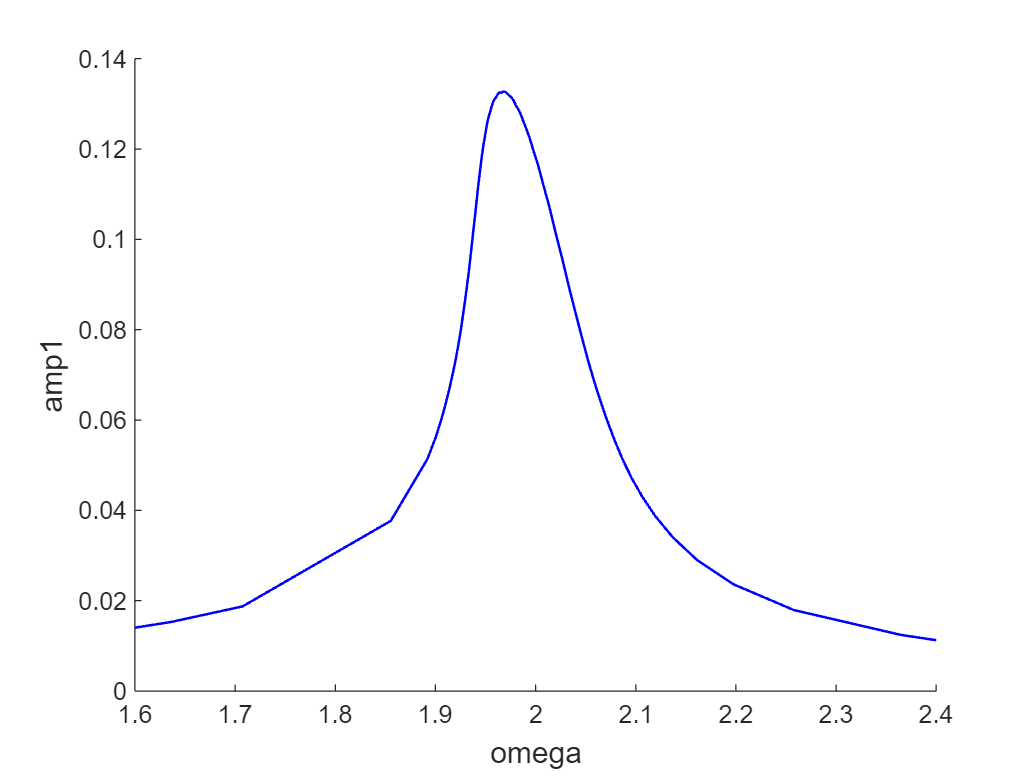

hold on
coco_plot_bd('func.forwardFRC','omega','amp1');